## Bons modos?

% clc;
% clear all;
% close all;

## lendo csv

M = readmatrix('SIRpd')

M =   499.0000    1.0000         0
  498.9490    1.0407    0.0102
  498.8960    1.0831    0.0208
  498.8408    1.1273    0.0319
  498.7834    1.1732    0.0434
  498.7236    1.2210    0.0554
  498.6615    1.2707    0.0679
  498.5968    1.3224    0.0808
  498.5294    1.3762    0.0943
  498.4594    1.4322    0.1084



Sd = M(:,1)

Sd =   499.0000
  498.9490
  498.8960
  498.8408
  498.7834
  498.7236
  498.6615
  498.5968
  498.5294
  498.4594


Id = M(:,2)

Id =     1.0000
    1.0407
    1.0831
    1.1273
    1.1732
    1.2210
    1.2707
    1.3224
    1.3762
    1.4322


Rd = M(:,3)

Rd =          0
    0.0102
    0.0208
    0.0319
    0.0434
    0.0554
    0.0679
    0.0808
    0.0943
    0.1084


## O corno do gauss n tem nada pra fazer, então ele inventou a porra dum ruido vtnc

a = 0;
b = mean(Sd)/10;
c = mean(Id)/5;
d = mean(Rd)/10;
Sdn = (b-a).*rand(length(Sd),1) + a

Sdn =     2.5817
    5.6984
    1.5810
    6.8655
    6.4122
    1.6247
    3.5453
    5.4154
    4.5887
    0.7385


Idn = (c-a).*rand(length(Id),1) + a

Idn =     9.5508
    9.7159
    7.7681
    2.8032
    3.3276
    6.9031
    2.3773
    5.4498
    6.8736
    4.3546


Rdn = (d-a).*rand(length(Rd),1) + a

Rdn =    29.7058
   24.7166
   29.1787
    1.5727
    1.7636
    2.0479
   33.5630
    9.0755
   20.1169
   14.1116


## some da minha vida

Sdnew = Sd + Sdn

Sdnew =   501.5817
  504.6475
  500.4770
  505.7063
  505.1956
  500.3483
  502.2068
  504.0122
  503.1181
  499.1979


Idnew = Id + Idn

Idnew =    10.5508
   10.7567
    8.8513
    3.9304
    4.5008
    8.1240
    3.6480
    6.7722
    8.2498
    5.7869


Rdnew = Rd + Rdn

Rdnew =    29.7058
   24.7268
   29.1995
    1.6046
    1.8070
    2.1033
   33.6309
    9.1564
   20.2112
   14.2200


## plotano

tempo = linspace(0,length(Sd),length(Sd))

tempo = 	1.0e+03 *

         0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


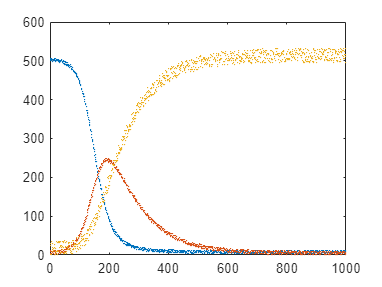


plot(tempo,Sdnew, '.' , 'markersize',0.8)
hold on;
plot(tempo,Idnew, '.' , 'markersize',0.8)
plot(tempo,Rdnew, '.' , 'markersize',0.8)
hold off;

## agora que fode

R0 = 0

R0 = 0

I0 = 499

I0 = 499

S0 = 1

S0 = 1

r = 0.1

r = 0.1000

beta = 0.0001

beta = 1.0000e-04

model = sim("ModeloSIR.slx")

model =   Simulink.SimulationOutput:

                logsout: [1x1 Simulink.SimulationData.Dataset] 
                   tout: [100005x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


SdValues = model.logsout{1}.Values.Data

SdValues =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.9999
    0.9999
    0.9998
    0.9998
    0.9997


IdValues = model.logsout{2}.Values.Data

IdValues =   499.0000
  498.9998
  498.9988
  498.9938
  498.9687
  498.9188
  498.8690
  498.8192
  498.7693
  498.7195


RdValues = model.logsout{3}.Values.Data

RdValues =          0
    0.0002
    0.0012
    0.0062
    0.0313
    0.0812
    0.1311
    0.1810
    0.2309
    0.2808


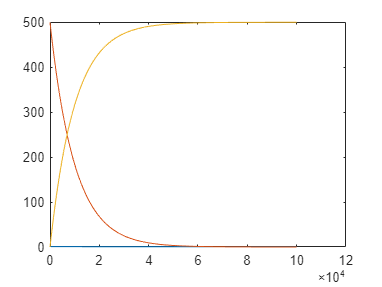

plot(SdValues)
hold on;
plot(IdValues)
plot(RdValues)
hold off;

## calculando o erro???